# Structural Testing:

# Test file for return winsorising & covaraince regulirisation

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 31/08/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

**NEEDED DATA: **

**ASSET Px_Last**

"DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat"

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

Set path for data helper functions

% Add /functions directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Toolboxes//datahelpers/functions/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Structural_Testing/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

**Set Directories & Load Data**

Load Processed Signal and Asset Class data

fileName = 'DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
load(fileName)

x = M_Ret_TT.INDI25_Index;
test_winsor = winsor(x,[10 90]);

histogram(x);
histogram(test_winsor);

% Return_matrix = table2array(M_Ret_TT);
Return_matrix = M_Ret_TT.INDI25_Index;

[wx,b,ui,li] = tim_winsor(Return_matrix);

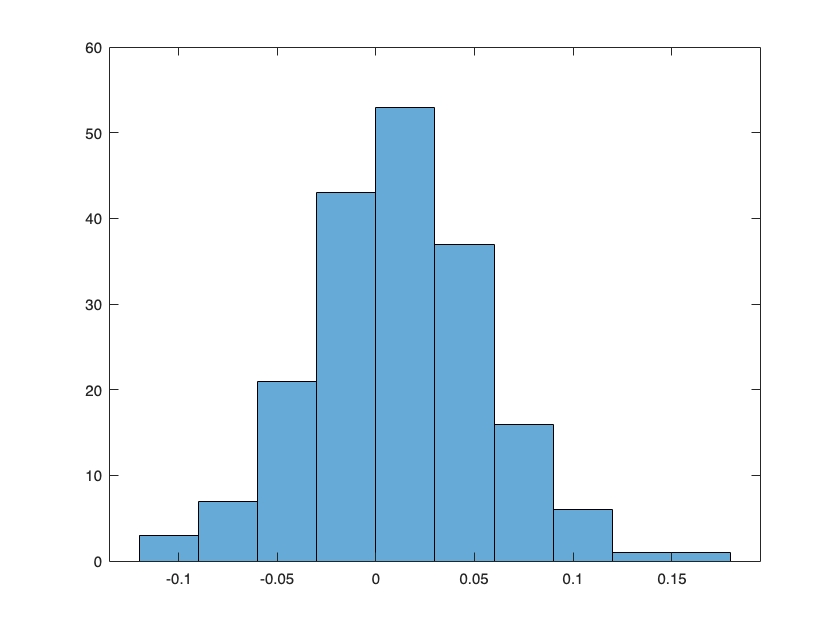

histogram(Return_matrix)

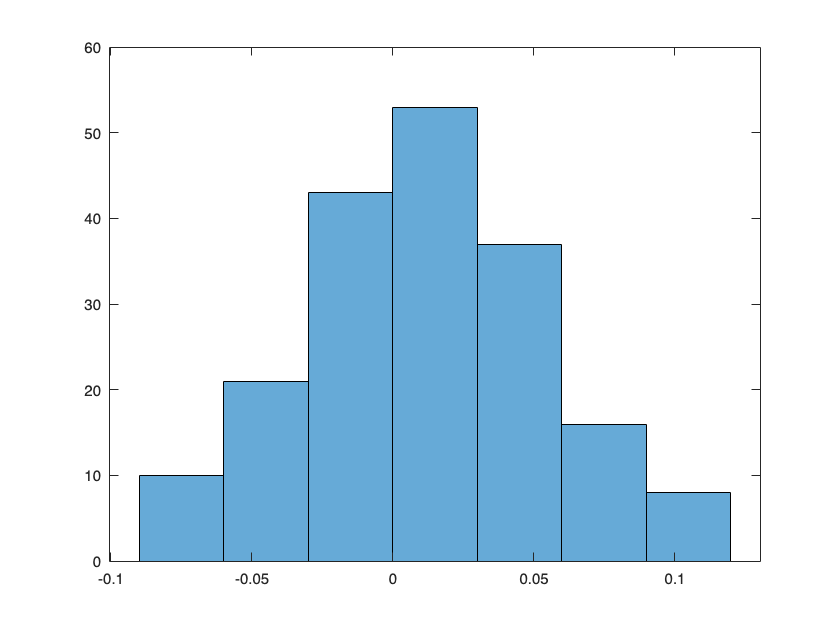

histogram(wx)